# Задание 1

a_2 = 9;
a_1 = 23;
a_0 = 15;
b_2 = 14;
b_1 = 6;
b_0 = 16;

Рассмотрим ДУ$\dddot{y}+a_2\ddot{y}+a_1\dot{y}+a_0y=b_2\ddot{u}+b_1\dot{u}+b_0u$

Перепишем в более удобном варианте для создания структурной схемы в Simulink


$$y=\frac{1}{p}\left(b_2u-a_2y+\frac{1}{p}\left(b_1u-a_1y+\frac{1}{p}\left(b_0u-a_0y\right)\right)\right)$$


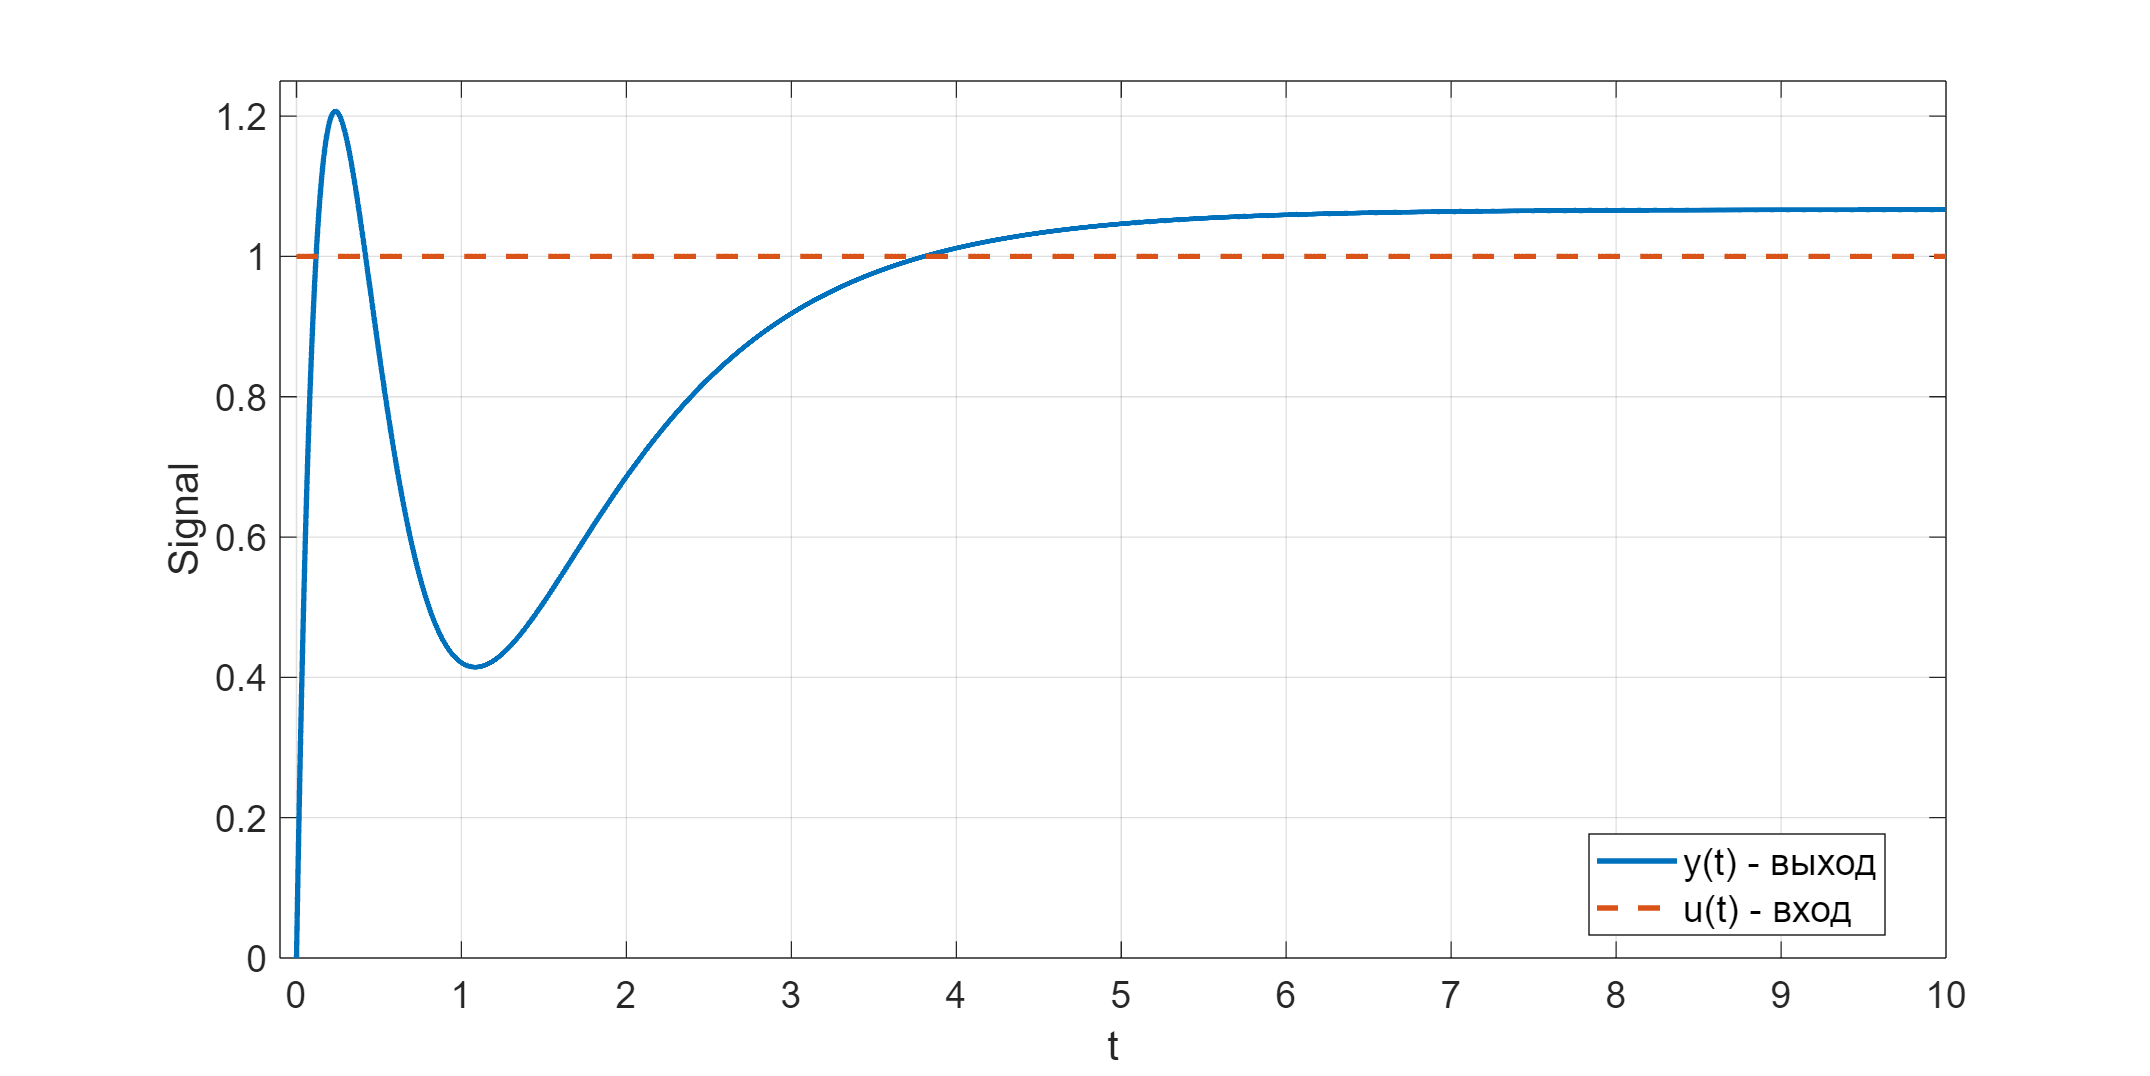

simtime = 10;
plot_1 = sim("lab1_1.slx", simtime);
plot(plot_1.y.Time, plot_1.y.Data, "LineWidth", 2, "LineStyle","-");
hold on;
plot(plot_1.u.Time, plot_1.u.Data, "Linewidth", 2, "Linestyle", "--");
xlim([-0.1 10.00]);
ylim([0.00 1.25]);
grid on;
legend("y(t) - выход", "u(t) - вход", "Location", "best", "FontSize", 14);
xlabel("t");
ylabel("Signal");
set(gcf, 'Position', [100, 100, 1200, 600]);
set(gca, 'FontSize', 14); 
hold off;

# Задание 2

Найдём передаточную функцию из нашего ДУ


$$(p^3+a_2p^2+a_1p+a_0)y=(b_2p^2+b_1p+b_0)u$$



$$y=\frac{b_2p^2+b_1p+b_0}{p^3+a_2p^2+a_1p+a_0}[u]\Rightarrow W(p)=\frac{b_2p^2+b_1p+b_0}{p^3+a_2p^2+a_1p+a_0}$$


Если подставить коэффициенты: $W(p)=\frac{14p^2+6p+16}{p^3+9p^2+23p+15}$

Построим математические модели:

Общий вид матричной записи:


$$W(p)=(C(Ip-A)^{-1}B+D)$$


- Каноническая управляемая форма


$$A_y=
\pmatrix{
0 & 1 & 0 \cr
0 & 0 & 1 \cr
-\frac{a_0}{a_3} & -\frac{a_1}{a_3} & -\frac{a_2}{a_3}
}=
\pmatrix{
0 & 1 & 0 \cr
0 & 0 & 1\cr
-15 & -23 & -9
},\quad
B_y=\pmatrix{0\cr0\cr1}
\\
C_y=\pmatrix{\frac{b_0}{a_3} & \frac{b_1}{a_3} & \frac{b_2}{a_3}}=\pmatrix{16 & 6 & 14},\quad D_y=[d]=[0]$$


$a_3$ в нашем случае равно 1, $d=0$.

- Каноническая наблюдаемая форма


$$A_н = 
\pmatrix{
0 & 0 & -\frac{a_0}{a_3} \cr
1 & 0 & -\frac{a_1}{a_3} \cr
0 & 1 & -\frac{a_2}{a_3}
}=\pmatrix{
0 & 0 & -15 \cr
1 & 0 & -23 \cr
0 & 1 & -9
},\quad
B_н = \pmatrix{\frac{b_0}{a_3} \cr \frac{b_1}{a_3} \cr \frac{b_2}{a_3}} = \pmatrix{16 \cr 6 \cr 14}
\\
C_н = \pmatrix{0 & 0 & 1},\quad D_H = [d] = [0]$$


- Каноническая диагональная форма


$$A_д=\pmatrix{\lambda_1 & 0 & 0\cr
0 & \lambda_2 & 0\cr
0 & 0 & \lambda_3},\quad B_д=\pmatrix{\beta_0\cr \beta_1\cr \beta_2},\quad
C_д=\pmatrix{1 & 1 & 1}$$



$$\text{Найдём коэффициенты $\lambda$}:\\
p^3+9p^2+23p+15=0\\
\lambda_1=-1\\
\frac{p^3+9p^2+23p+15}{p+1}=p^2+8p+15\Rightarrow \lambda_2=-3,\quad \lambda_3=-5\\
\text{Выразим $\beta$}:\\
\frac{14p^2+6p+16}{(p+1)(p+3)(p+5)}=\frac{\beta_1}{p+1}+\frac{\beta_2}{p+3}+\frac{\beta_3}{p+5}\\
\beta_1(p^2+8p+15)+\beta_2(p^2+6p+5)+\beta_3(p^2+4p+3)=14p^2+6p+16\\
\begin{cases}
\beta_1+\beta_2+\beta_3=14\\
8\beta_1+6\beta_2+4\beta_3=6\\
15\beta_1+5\beta_2+3\beta_3=16
\end{cases}$$


A = [1, 1, 1;
     8, 6, 4;
     15, 5, 3];
B = [14; 6; 16];
X = A \ B

X =     3.0000
  -31.0000
   42.0000



$$\beta_1=3,\quad\beta_2=-31,\quad\beta_3=42$$


Получаем каноническую диагональную форму:


$$A_д=\pmatrix{-1 & 0 & 0\cr
0 & -3 & 0\cr
0 & 0 & -5},\quad B_д=\pmatrix{3\cr -31\cr 42},\quad
C_д=\pmatrix{1 & 1 & 1}$$


lam_1 = -1;
lam_2 = -3;
lam_3 = -5;
beta_1 = 3;
beta_2 = -31;
beta_3 = 42;

Моделируем:

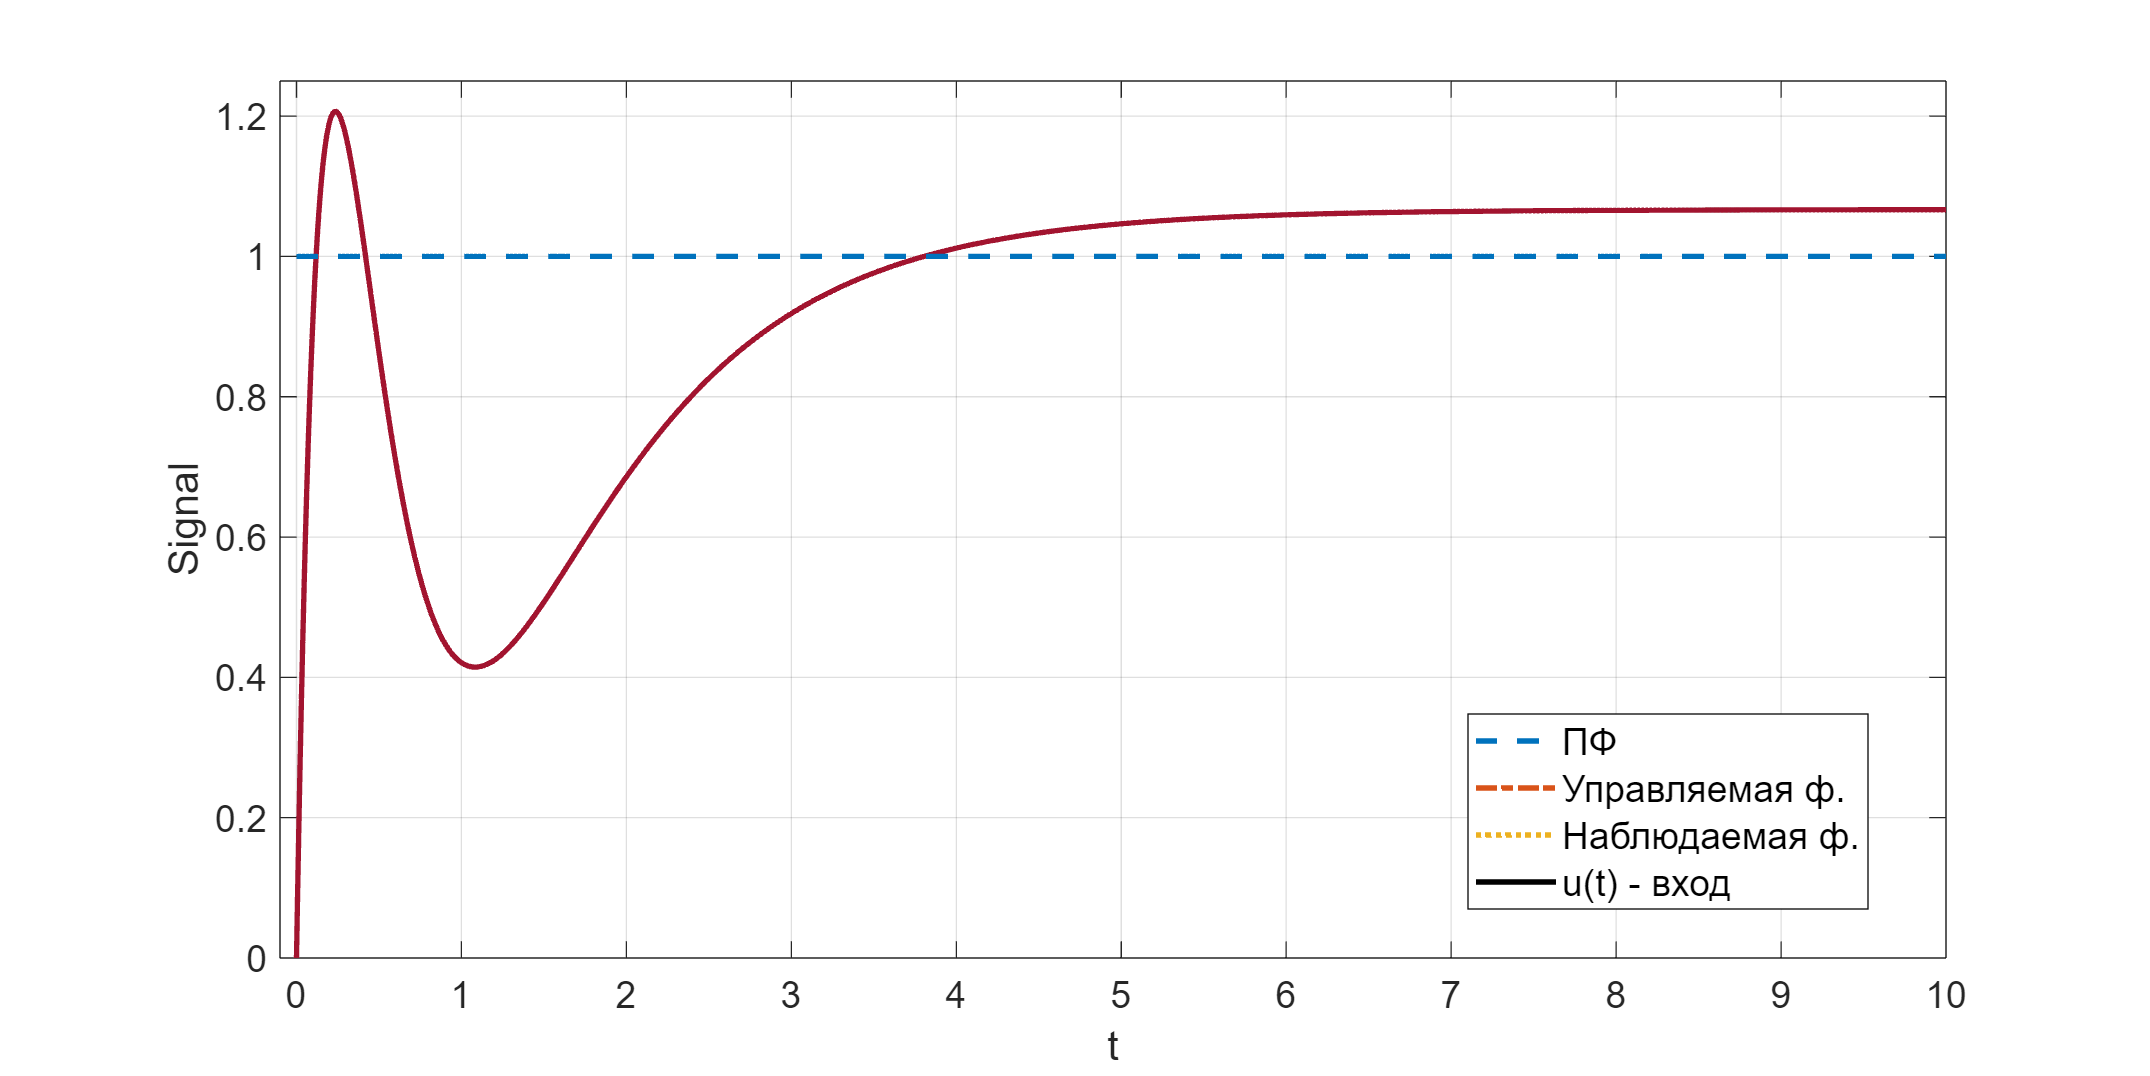

simtime = 10;
plot_Tf = sim("lab1_2_Tf.slx", simtime);
plot_contr = sim("lab_1_2_contr.slx", simtime);
plot_obs = sim("lab_1_2_obs.slx", simtime);
plot_diag = sim("lab_1_2_diag.slx", simtime);

plot(plot_Tf.y.Time, plot_Tf.y.Data, "LineWidth", 2, "LineStyle","--");
hold on;
plot(plot_contr.y.Time, plot_contr.y.Data, "LineWidth", 2, "LineStyle","-.");
hold on;
plot(plot_obs.y.Time, plot_obs.y.Data, "LineWidth", 2, "LineStyle",":");
hold on;
plot(plot_diag.y.Time, plot_diag.y.Data, "LineWidth", 2, "LineStyle", "-");
hold on;
plot(plot_Tf.u.Time, plot_Tf.u.Data, "Linewidth", 2, "Linestyle", "--");

xlim([-0.1 10.00]);
ylim([0.00 1.25]);
grid on;
legend("ПФ", "Управляемая ф.", "Наблюдаемая ф.", "u(t) - вход", "Location", "best", "FontSize", 14);
xlabel("t");
ylabel("Signal");
set(gcf, 'Position', [100, 100, 1200, 600]);
set(gca, 'FontSize', 14); 
hold off;